# PROYECTO: Análisis de IPs maliciosas en la zona ARIN (2013 - 2019)

*Realizado por: Abel Castillo González, Marc Donato Merí, Iván Martínez Castellot, Andrés Nadal Manzanares, Ruben Saiz López, Rubén Vilanova Candel y David Maudos Soriano*

En este proyecto analizamos qué ha pasado con las direcciones IP maliciosas de la zona ARIN entre 2013 y 2019. Partimos del fichero de reputación de 2013 del libro y lo comparamos con el de 2019 que hemos usado en clase.

ARIN (American Registry for Internet Numbers) es el organismo que gestiona la asignación de IPs en Norteamérica, el Caribe y parte del Atlántico Norte.

## Reparto de Tareas

Abel Castillo González & Marc Donato Merí: Desarrollo del código de la Parte 1 (Explorando), limpieza de datos y cruce de ficheros de reputación con los delegados de ARIN.

Iván Martínez Castellot & Andrés Nadal Manzanares: Desarrollo de la Parte 2 (Regresión), normalización de datos ITU y cruce de códigos ISO2/ISO3.

Ruben Saiz López & Rubén Vilanova Candel: Diseño e implementación de la Parte 3 (Mapeando), generación de mapas Choropleth y aplicación de escalas logarítmicas.

David Maudos Soriano: Desarrollo de la Parte 4 (Aprendiendo), implementación de FileDatastore para el análisis de incidentes JSON y redacción de conclusiones globales.

## Introducción y Metodología

El objetivo de este proyecto es analizar la evolución de las amenazas cibernéticas en la zona ARIN (Norteamérica y partes del Caribe) entre los años 2013 y 2019. Para abordar el trabajo, hemos dividido el proyecto en cuatro fases interconectadas:

Exploración y Filtrado: Comenzamos procesando los datos en bruto de ARIN para aislar las IPs IPv4 y los Sistemas Autónomos (ASN) válidos, cruzándolos matemáticamente con los listados de reputación maliciosa para descubrir qué IPs maliciosas residen en nuestra zona de estudio.

Análisis Estadístico (Regresión): Buscamos responder si existe una correlación directa entre el nivel de desarrollo tecnológico de un país (usando datos de la ITU) y su volumen de IPs maliciosas.

Análisis Geográfico (Mapeando): Visualizamos la distribución territorial de las amenazas mediante mapas Choropleth, lo que nos permite entender visualmente la concentración de la infraestructura maliciosa.

Análisis de Incidentes (Aprendiendo): Finalmente, damos un contexto humano a los números analizando una base de datos real de incidentes (VCDB) para descubrir quién ataca, cómo lo hace y por qué.

## Explorando

1. Empezamos cargando el fichero delegated de arin

dele = LoadArin("delegated_arin.txt");

*Nota sobre funciones propias: La función LoadArin (ubicada en un archivo .m externo) se encarga de leer el fichero de texto plano delegated_arin.txt, descartar los comentarios iniciales y estructurar los datos en una tabla de MATLAB separando por el delimitador |, asignando nombres a las columnas (organización, código de país, tipo, IP, valor, fecha y estado) para facilitar su filtrado posterior.*

 2. Filtramos las filas de tipo IPv4, ya que son las que nos interesan para este análisis, descartando los registros de tipo ASN e IPv6. Además, dentro de las IPv4 nos quedamos únicamente con aquellas cuyo estado es `allocated` o `assigned`, que son las que corresponden a bloques de direcciones realmente asignados a organizaciones o proveedores, descartando los registros en estado `available` o `reserved` que no están en uso activo.

Lia_ipv4 = dele.tipo == "ipv4";
dele4 = dele(Lia_ipv4, :);

Lia_estado1 = dele4.estado == "allocated" | dele4.estado == "assigned";
dele4 = dele4(Lia_estado1, :);

fprintf("Número de rangos IPv4 en ARIN: %d\n", height(dele4));

Número de rangos IPv4 en ARIN: 64218


3. Hacemos lo mismo para las ASN

Lia_asn = dele.tipo == "asn";
dele_asn = dele(Lia_asn, :);

Lia_estado2 = dele_asn.estado == "allocated" | dele_asn.estado == "assigned";
dele_asn = dele_asn(Lia_estado2, :);

fprintf("Número de ASNs en ARIN: %d\n", height(dele_asn));

Número de ASNs en ARIN: 27450


 4. Sacamos las IPs  y valores del fichero delegated y los convertimos a decimal

*Para poder comparar si una IP de reputation está dentro de un rango ARIN, necesitamos pasar todo a números. Por ejemplo, una IP como 23.5.1.0 se convierte haciendo:  *

*23*(256^3) + 5*(256^2) + 1*256 + 0*

Ip_dele = dele4.ip;
valor_dele = dele4.valor;

lista_inicio_decimal = zeros(length(Ip_dele), 1);
lista_fin_decimal = zeros(length(Ip_dele), 1);

% ¿Por qué pasamos a decimal? Las direcciones IP en formato texto (ej: 192.168.0.1) 
% no se pueden comparar fácilmente para saber si están dentro de un rango. 
% Al convertirlas a un número entero absoluto, el problema se reduce a una 
% simple comprobación matemática: if (IP_maliciosa >= inicio_rango)...

for i = 1:length(Ip_dele)
    ip_texto = Ip_dele{i};
    valor = valor_dele(i);
    trozos = split(ip_texto, ".");
    trozos_num = str2double(trozos);
    ip_decimal = trozos_num(1)*(256^3) + trozos_num(2)*(256^2) + trozos_num(3)*256 + trozos_num(4);
    limite_superior = ip_decimal + valor - 1;
    lista_inicio_decimal(i) = ip_decimal;
    lista_fin_decimal(i) = limite_superior;
end

  5. Abrimos el fichero de reputation 2019 y filtramos las IPs de ARIN

reputation_2019 = LeerRep("reputation_2019");
fprintf("Total IPs en reputation 2019: %d\n", height(reputation_2019));

Total IPs en reputation 2019: 55153


% Convertimos las IPs de reputation a decimal para poder compararlas con los rangos
Ip_reputation = reputation_2019.IP; 
lista_pos = false(length(Ip_reputation), 1);
ips_repu_numericas = zeros(length(Ip_reputation), 1);

for k = 1:length(Ip_reputation)
    trozos = split(Ip_reputation{k}, '.');
    trozos_num = str2double(trozos);
    ips_repu_numericas(k) = trozos_num(1)*(256^3) + trozos_num(2)*(256^2) + trozos_num(3)*256 + trozos_num(4);
end

Ahora comparamos cada IP con todos los rangos de ARIN

for i = 1:length(lista_fin_decimal)
    ip_inferior = lista_inicio_decimal(i);
    ip_superior = lista_fin_decimal(i);
    for x = 1:length(Ip_reputation)
        ip_decimal = ips_repu_numericas(x);
        if (ip_decimal >= ip_inferior) && (ip_decimal <= ip_superior)
            lista_pos(x) = true;
        end
    end
end

reputation_arin_2019 = reputation_2019(lista_pos, :);
fprintf("IPs de ARIN en reputation 2019: %d\n", height(reputation_arin_2019));

IPs de ARIN en reputation 2019: 7643


Hacemos lo mismo para reputation 2013

reputation_2013 = LeerRep("reputation_2013");
fprintf("Total IPs en reputation 2013: %d\n", height(reputation_2013));

Total IPs en reputation 2013: 258626


Ip_reputation = reputation_2013.IP;
lista_pos_2 = false(length(Ip_reputation), 1);
ips_repu_numericas = zeros(length(Ip_reputation), 1);

for k = 1:length(Ip_reputation)
    trozos = split(Ip_reputation{k}, '.');
    trozos_num = str2double(trozos);
    ips_repu_numericas(k) = trozos_num(1)*(256^3) + trozos_num(2)*(256^2) + trozos_num(3)*256 + trozos_num(4);
end

Comparando con ARIN...

for i = 1:length(lista_fin_decimal)
    ip_inferior = lista_inicio_decimal(i);
    ip_superior = lista_fin_decimal(i);
    for x = 1:length(Ip_reputation)
        ip_decimal = ips_repu_numericas(x);
        if (ip_decimal >= ip_inferior) && (ip_decimal <= ip_superior)
            lista_pos_2(x) = true;
        end
    end
end

reputation_arin_2013 = reputation_2013(lista_pos_2, :);
fprintf("IPs de ARIN en reputation 2013: %d\n", height(reputation_arin_2013));

IPs de ARIN en reputation 2013: 56589


*Nota sobre funciones propias: La función LeerRep abre los ficheros CSV de reputación (2013 y 2019). Su labor principal es leer los datos en crudo y devolver una tabla estructurada (reputation_2013 o reputation_2019) con las IPs y sus metadatos (país, ciudad, tipo de amenaza), lista para ser cruzada con los rangos de ARIN.*

Comparamos qué IPs aparecen en ambos ficheros

ips_coincidentes = intersect(reputation_arin_2013.IP, reputation_arin_2019.IP);
fprintf("IPs ARIN en 2013:             %d\n", height(reputation_arin_2013));

IPs ARIN en 2013:             56589


fprintf("IPs ARIN en 2019:             %d\n", height(reputation_arin_2019));

IPs ARIN en 2019:             7643


fprintf("IPs que aparecen en los dos:  %d\n", length(ips_coincidentes));

IPs que aparecen en los dos:  8


fprintf("IPs que desaparecieron:       %d (%.1f%%)\n", ...
    height(reputation_arin_2013) - length(ips_coincidentes));

IPs que desaparecieron:       56581 (

disp("IPs que siguen siendo maliciosas en 2019:");

IPs que siguen siendo maliciosas en 2019:


disp(ips_coincidentes);

    "192.241.209.207"
    "198.20.70.114"
    "204.42.253.132"
    "204.42.253.136"
    "204.42.253.137"
    "204.42.253.138"
    "204.42.253.139"
    "24.44.18.228"



6. De las 8 IPs que siguen siendo maliciosas, veamos si ha cambiado algo en ellas...

for i = 1:length(ips_coincidentes)
    ip = ips_coincidentes{i};
    fila13 = reputation_arin_2013(strcmp(reputation_arin_2013.IP, ip), :);
    fila19 = reputation_arin_2019(strcmp(reputation_arin_2019.IP, ip), :);
    
    fprintf('\nIP: %s\n', ip);
    fprintf('  2013 -> País: %s | Ciudad: %s | Tipo: %s\n', ...
        char(fila13.paises), char(fila13.ciudades), char(fila13.tipo));
    fprintf('  2019 -> País: %s | Ciudad: %s | Tipo: %s\n', ...
        char(fila19.paises), char(fila19.ciudades), char(fila19.tipo));
end


IP: 192.241.209.207


  2013 -> País: <undefined> | Ciudad: <undefined> | Tipo: Scanning Host


  2019 -> País: US | Ciudad: San Francisco | Tipo: Malicious Host



IP: 198.20.70.114


  2013 -> País: US | Ciudad: Chicago | Tipo: Scanning Host


  2019 -> País: US | Ciudad: Chicago | Tipo: Malicious Host



IP: 204.42.253.132


  2013 -> País: US | Ciudad: Englewood | Tipo: Scanning Host


  2019 -> País: US | Ciudad: <undefined> | Tipo: Malicious Host



IP: 204.42.253.136


  2013 -> País: US | Ciudad: Englewood | Tipo: Scanning Host


  2019 -> País: US | Ciudad: <undefined> | Tipo: Malicious Host



IP: 204.42.253.137


  2013 -> País: US | Ciudad: Englewood | Tipo: Scanning Host


  2019 -> País: US | Ciudad: <undefined> | Tipo: Malicious Host



IP: 204.42.253.138


  2013 -> País: US | Ciudad: Englewood | Tipo: Scanning Host


  2019 -> País: US | Ciudad: <undefined> | Tipo: Malicious Host



IP: 204.42.253.139


  2013 -> País: US | Ciudad: Englewood | Tipo: Scanning Host


  2019 -> País: US | Ciudad: <undefined> | Tipo: Malicious Host



IP: 24.44.18.228


  2013 -> País: US | Ciudad: Bayonne | Tipo: Scanning Host


  2019 -> País: US | Ciudad: East Northport | Tipo: Malicious Host


Los resultados muestran que todas las IPs coincidentes entre 2013 y 2019 pertenecen a Estados Unidos, lo que confirma su posición dominante en la zona ARIN. Un patrón que se repite de forma consistente es el cambio de tipo de amenaza: prácticamente todas las IPs que en 2013 aparecían clasificadas como *Scanning Host* pasan a figurar como *Malicious Host*en 2019, lo que sugiere una evolución en la naturaleza de la actividad maliciosa, pasando de un comportamiento exploratorio o de reconocimiento a una actividad directamente dañina. Además, algunos registros pierden información de ciudad entre un año y otro (aparecen como `<undefined>`), lo que puede indicar cambios en la geolocalización de esas IPs o simplemente una cobertura menor en el fichero de 2019.

7. Gráfica comparando total IPs maliciosas en 2013 y 2019

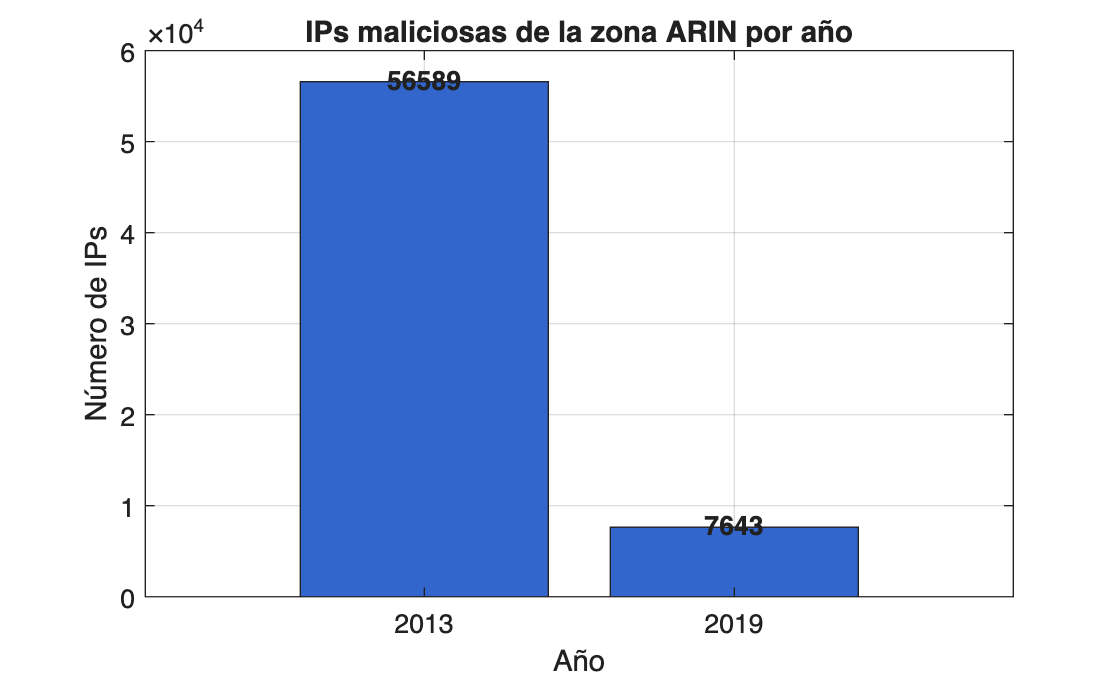

figure;
valores = [height(reputation_arin_2013), height(reputation_arin_2019)];
etiquetas = categorical({'2013', '2019'});
bar(etiquetas, valores, 'FaceColor', [0.2 0.4 0.8]);
title('IPs maliciosas de la zona ARIN por año');
ylabel('Número de IPs');
xlabel('Año');
grid on;
% Añadimos los números encima de las barras
text(1, valores(1) + 300, num2str(valores(1)), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
text(2, valores(2) + 300, num2str(valores(2)), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');

Tal y como refleja la gráfica de barras, existe una diferencia drástica en el volumen total de IPs maliciosas detectadas en la zona ARIN entre 2013 y 2019. Esta variación general puede deberse a dos factores: un endurecimiento en las políticas de reasignación de IPs por parte de ARIN a lo largo de esos 6 años, o bien que los cibercriminales hayan empezado a migrar su infraestructura maliciosa hacia otras regiones del mundo (RIPE, APNIC) con legislaciones más laxas.

8. Vemos de qué países vienen las IPs maliciosas....

tbl_paises_2013 = groupsummary(reputation_arin_2013, "paises");
tbl_paises_2013 = sortrows(tbl_paises_2013, "GroupCount", "descend");

tbl_paises_2019 = groupsummary(reputation_arin_2019, "paises");
tbl_paises_2019 = sortrows(tbl_paises_2019, "GroupCount", "descend");

fprintf("\n--- RESUMEN POR PAÍS 2013 ---\n");


--- RESUMEN POR PAÍS 2013 ---


disp(tbl_paises_2013);

      paises       GroupCount
    ___________    __________

    US               48661   
    CA                3046   
    <undefined>       2681   
    CN                 739   
    NL                 271   
    A1                 265   
    HK                 257   
    PE                 256   
    GB                 110   
    DE                  66   
    TR                  54   
    IN                  41   
    RU                  19   
    UA                  16   
    VG                  15   
    AU                  13   
    AE                  10   
    SA                   9   
    SG                   8   
    AR                   7   
    CZ                   7   
    PR                   7   
    IL                   4   
    BS                   2   
    CY                   2   
    EG                   2   
    ES                   2   
    JM                   2   
    A2                   1   
 

fprintf("--- RESUMEN POR PAÍS 2019 ---\n");

--- RESUMEN POR PAÍS 2019 ---


disp(tbl_paises_2019);

      paises       GroupCount
    ___________    __________

    US                6068   
    CA                 509   
    EU                 192   
    <undefined>        145   
    PR                 125   
    DE                  93   
    NL                  91   
    SG                  89   
    JP                  57   
    IN                  47   
    GB                  38   
    BS                  26   
    JM                  20   
    LU                  18   
    IE                  17   
    FR                  15   
    AU                  14   
    HK                  14   
    ES                  13   
    AP                   9   
    BB                   6   
    IT                   6   
    BR                   5   
    CN                   5   
    GD                   3   
    KR                   3   
    MX                   2   
    AE                   1   
    AR                   1   
 

*Nota: Los resultados de estas tablas se representan de forma más visual en las gráficas situadas más adelante en el documento, donde además se incluye una conclusión.*

9. Ahora, veamos qué tipos de amenazas se repiten más en cada año. Para ello vamos a crear unos pie plots que nos permitan comparar visualmente la proporción de cada categoría de amenaza en 2013 y en 2019.

tbl_tipo_2013 = groupsummary(reputation_arin_2013, "tipo");
tbl_tipo_2013 = sortrows(tbl_tipo_2013, "GroupCount", "descend");

tbl_tipo_2019 = groupsummary(reputation_arin_2019, "tipo");

fprintf("\n--- TIPOS DE AMENAZA 2013 ---\n");


--- TIPOS DE AMENAZA 2013 ---


disp(tbl_tipo_2013);

                tipo                 GroupCount
    _____________________________    __________

    Scanning Host                      47776   
    Malware Domain                      2876   
    Malware IP                          2600   
    Spamming                            2193   
    Malicious Host                       652   
    C&C                                  200   
    Malware Domain;Malware IP             67   
    Scanning Host;Malicious Host          57   
    Malicious Host;Scanning Host          48   
    Malware IP;Malware Domain             28   
    Spamming;Scanning Host                16   
    Malware Domain;C&C                    14   
    C&C;Malware IP                        10   
    Malware Domain;Scanning Host           9   
    C&C;Malware Domain                     7   
    Malware IP;Spamming                    7   
    Malware IP;Scanning Host               6   
    Spamming;Malwar

fprintf("--- TIPOS DE AMENAZA 2019 ---\n");

--- TIPOS DE AMENAZA 2019 ---


disp(tbl_tipo_2019);

         tipo         GroupCount
    ______________    __________

    Malicious Host       7643   



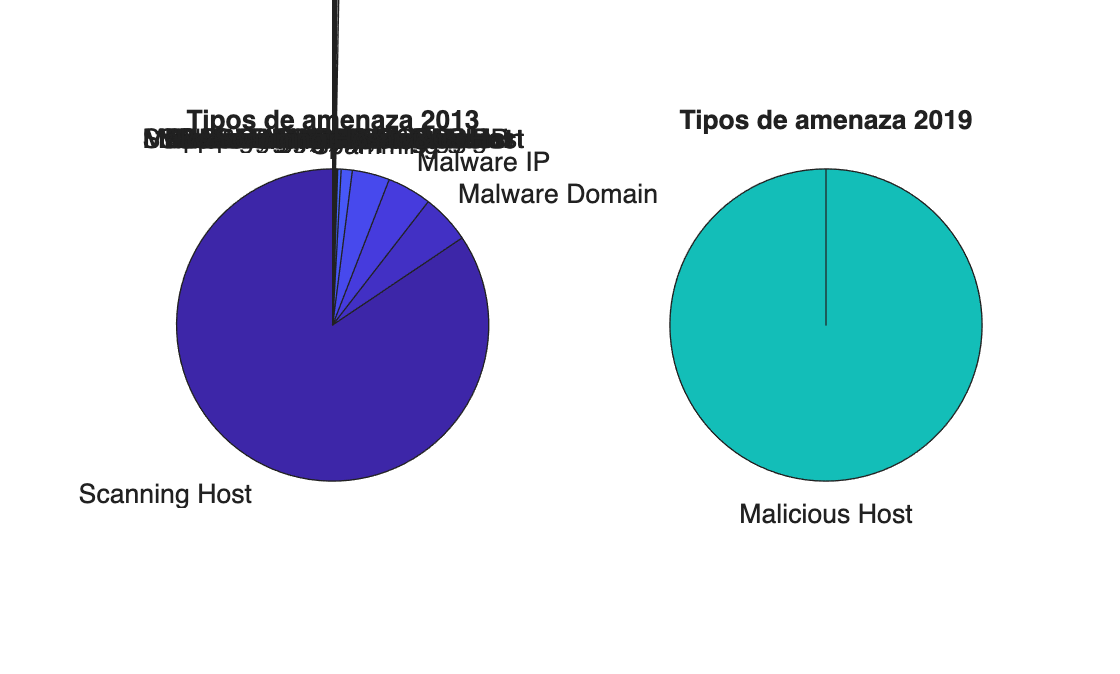

figure;
subplot(1, 2, 1);
pie(tbl_tipo_2013.GroupCount, cellstr(tbl_tipo_2013.tipo));
title('Tipos de amenaza 2013');

subplot(1, 2, 2);
pie(tbl_tipo_2019.GroupCount, cellstr(tbl_tipo_2019.tipo));
title('Tipos de amenaza 2019');

Comparando ambas gráficas se aprecia una evolución del panorama de amenazas, claramente ha mutado el "modelo de negocio" cibercriminal. Mientras que en 2013 la amenaza predominante estaba relacionada con "Scanning Host", en 2019 el ecosistema evoluciona hacia "Malicious Host". Esto demuestra que los atacantes adaptan sus infraestructuras en ARIN según las tendencias de rentabilidad del momento.

Creamos unas gráficas que nos permitan ver mejor la distribución de IPs maliciosas por país y determinar cuáles concentran un mayor volumen, tanto en 2013 como en 2019, para poder comparar la evolución entre ambos años.

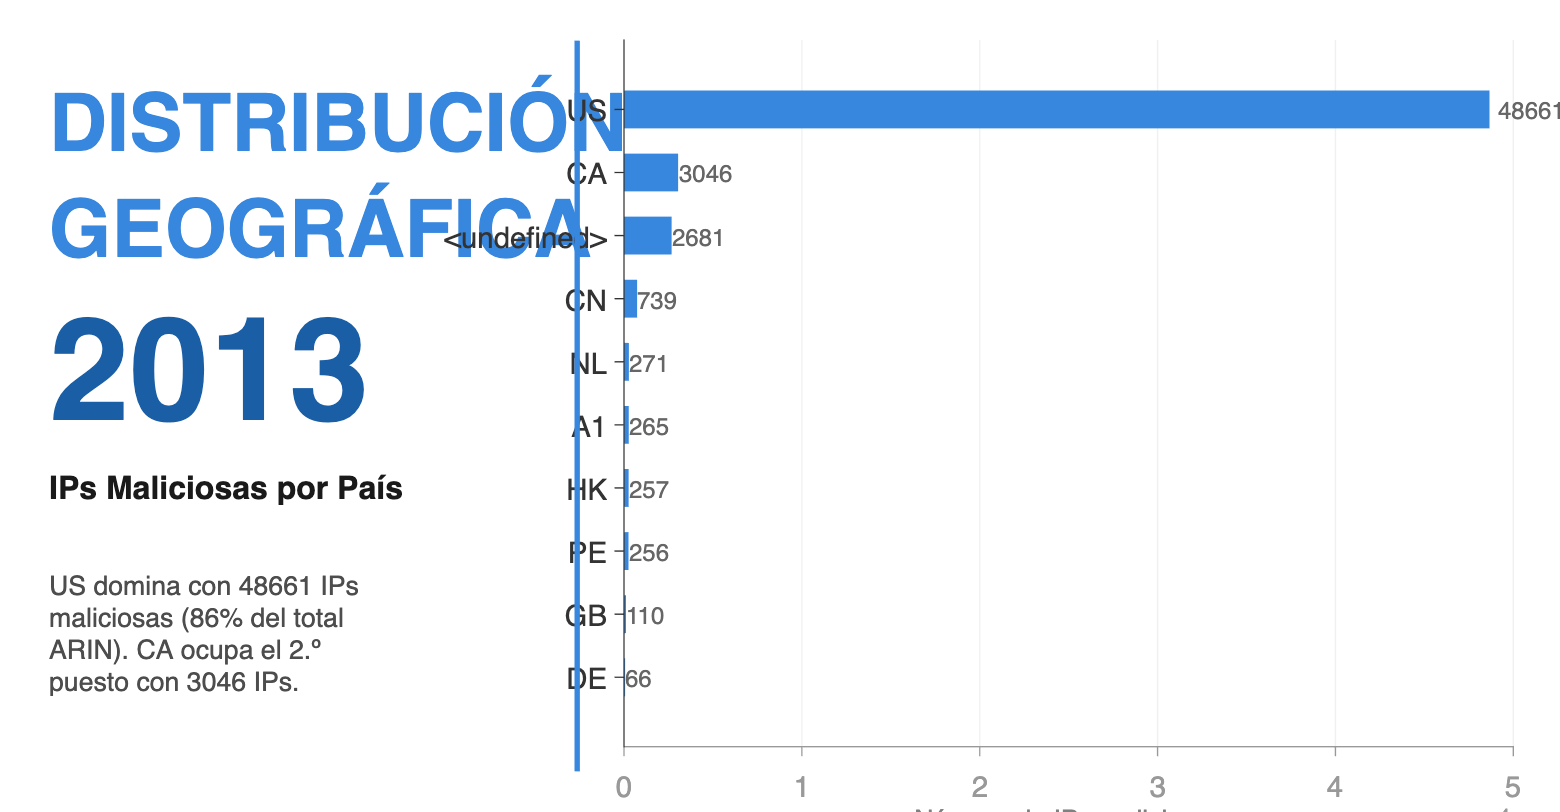


function infografico_paises(tbl, anyo)
    top_n = min(10, height(tbl));
    datos = tbl(1:top_n, :);
    total = sum(tbl.GroupCount);

    fig = figure('Color', 'white', 'Position', [100 100 1000 520]);

    ax_txt = axes('Position', [0 0 0.38 1], 'Visible', 'off');
    text(0.08, 0.85, 'DISTRIBUCIÓN', 'FontSize', 30, 'FontWeight', 'bold', ...
        'Color', [0.22 0.53 0.87], 'Units', 'normalized', 'Parent', ax_txt);
    text(0.08, 0.72, 'GEOGRÁFICA', 'FontSize', 30, 'FontWeight', 'bold', ...
        'Color', [0.22 0.53 0.87], 'Units', 'normalized', 'Parent', ax_txt);
    text(0.08, 0.55, num2str(anyo), 'FontSize', 54, 'FontWeight', 'bold', ...
        'Color', [0.10 0.37 0.65], 'Units', 'normalized', 'Parent', ax_txt);
    text(0.08, 0.40, 'IPs Maliciosas por País', 'FontSize', 12, ...
        'FontWeight', 'bold', 'Color', [0.1 0.1 0.1], 'Units', 'normalized', 'Parent', ax_txt);

    pct_1 = round(datos.GroupCount(1) / total * 100);
    desc = sprintf('%s domina con %s IPs\nmaliciosas (%d%% del total\nARIN). %s ocupa el 2.º\npuesto con %s IPs.', ...
        char(datos.paises(1)), num2str(datos.GroupCount(1)), pct_1, ...
        char(datos.paises(2)), num2str(datos.GroupCount(2)));
    text(0.08, 0.22, desc, 'FontSize', 10, 'Color', [0.3 0.3 0.3], ...
        'Units', 'normalized', 'Parent', ax_txt);

    annotation(fig, 'line', [0.37 0.37], [0.05 0.95], ...
        'Color', [0.22 0.53 0.87], 'LineWidth', 2);

    ax = axes('Position', [0.40 0.08 0.57 0.87]);
    barh(1:top_n, datos.GroupCount, 'FaceColor', [0.22 0.53 0.87], ...
        'EdgeColor', 'none', 'BarWidth', 0.6);
    set(ax, 'YTick', 1:top_n, 'YTickLabel', cellstr(datos.paises), ...
        'YDir', 'reverse', 'FontSize', 11, 'Box', 'off', ...
        'TickDir', 'out', 'Color', 'white');
    ax.XAxis.Color = [0.6 0.6 0.6];
    ax.YAxis.Color = [0.2 0.2 0.2];
    xlabel('Número de IPs maliciosas', 'FontSize', 10, 'Color', [0.5 0.5 0.5]);
    grid on; ax.GridAlpha = 0.15; ax.XGrid = 'on'; ax.YGrid = 'off';

    for i = 1:top_n
        text(datos.GroupCount(i) * 1.01, i, num2str(datos.GroupCount(i)), ...
            'FontSize', 9, 'Color', [0.4 0.4 0.4], 'VerticalAlignment', 'middle');
    end
end

infografico_paises(tbl_paises_2013, 2013);

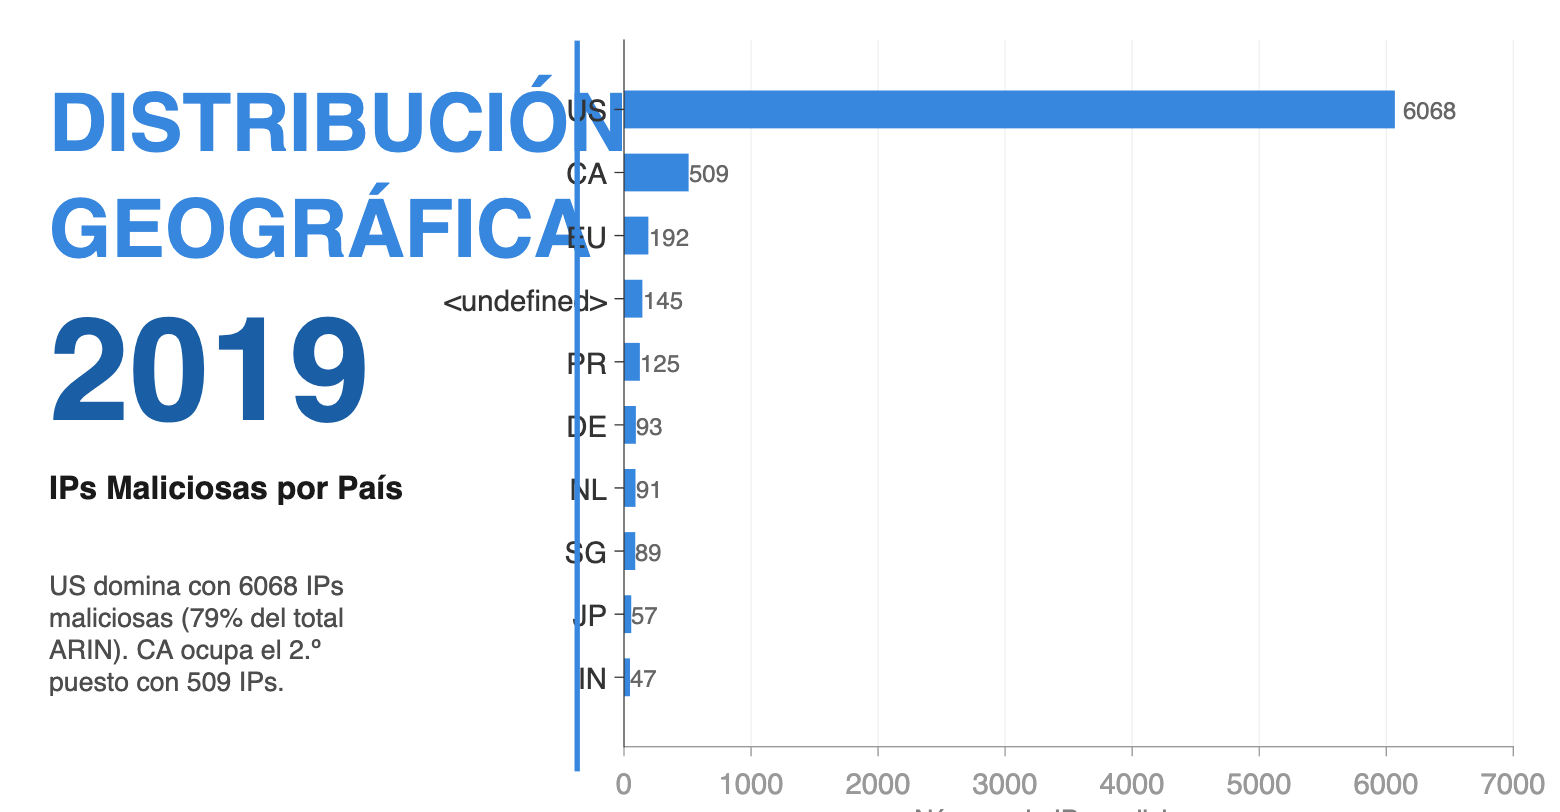

infografico_paises(tbl_paises_2019, 2019);

Observando estos infográficos, queda patente el peso abrumador que tiene Estados Unidos en la acumulación de IPs maliciosas, acaparando la inmensa mayoría del total de la zona ARIN en ambos años. Esto era esperable dada su colosal infraestructura de red. Sin embargo, lo interesante del análisis es fijarse en el resto de la tabla: al comparar 2013 con 2019, vemos cómo entran, salen o escalan posiciones otros países. Estos pequeños cambios en el ranking nos confirman que el cibercrimen es dinámico y va moviendo su infraestructura a aquellos países donde las condiciones le son más favorables.

*Nota sobre funciones propias: Hemos creado la función infografico_paises dentro del propio script para evitar repetir código. Esta función recibe una tabla de conteos por país y el año, y se encarga de generar automáticamente una gráfica de barras horizontales estilizada, calculando porcentajes y añadiendo un texto descriptivo dinámico sobre el país líder.*

10. ¿Qué países tienen más ASN asignados en ARIN?

tbl_asn_pais = groupsummary(dele_asn, "pais");
tbl_asn_pais = sortrows(tbl_asn_pais, "GroupCount", "descend");

fprintf("\n--- ASNs por país (top 10) ---\n");


--- ASNs por país (top 10) ---


disp(tbl_asn_pais(1:10, :));

    pais    GroupCount
    ____    __________

     US       25305   
     CA        1874   
     PR          85   
     BM          19   
     GB          17   
     KY          15   
     JM          13   
     VG          13   
     BB          11   
     BS          11   



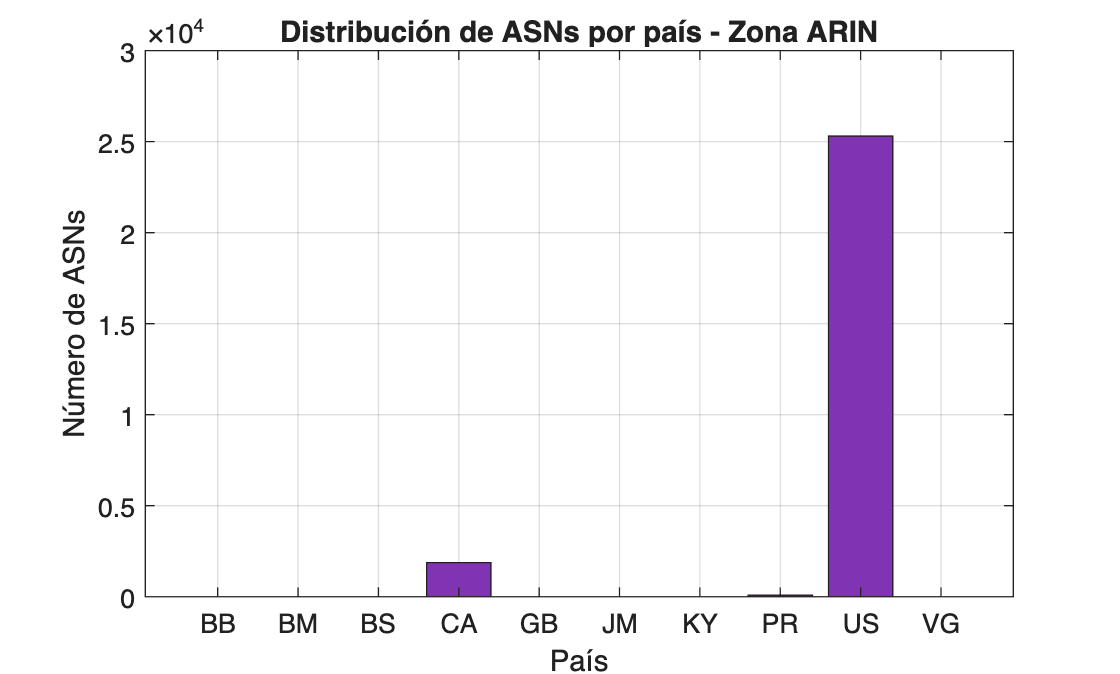

figure;
top_asn = tbl_asn_pais(1:10, :);

paises = categorical(top_asn.pais);
paises = removecats(paises);

bar(paises, top_asn.GroupCount, 'FaceColor', [0.5 0.2 0.7]);
title('Distribución de ASNs por país - Zona ARIN');
xlabel('País');
ylabel('Número de ASNs');
grid on;

Esta distribución de ASNs nos sirve como "línea base". Es completamente lógico que países como Estados Unidos o Canadá lideren esta tabla, ya que poseen la infraestructura de red más grande de la región ARIN. Por lo tanto, al analizar los países con más IPs maliciosas, siempre debemos tener en cuenta este factor de proporcionalidad: a mayor número de ASNs asignados, mayor probabilidad estadística de alojar IPs infectadas, aunque no implique necesariamente que el país sea más inseguro.

11. Construimos la lista de ASNs con su país

Asn_num = dele_asn.ip;
Asn_valor = dele_asn.valor;

lista_asn_num = [];
lista_asn_pais = {};

for i = 1:height(dele_asn)
    asn_inicio = str2double(Asn_num{i});
    cantidad = Asn_valor(i);
    pais_actual = char(dele_asn.pais(i));
    for k = 0:(cantidad - 1)
        lista_asn_num(end+1, 1) = asn_inicio + k;
        lista_asn_pais{end+1, 1} = pais_actual;
    end
end

tabla_asn = table(lista_asn_num, lista_asn_pais, ...
    'VariableNames', {'ASN', 'Pais'});
tbl_resumen = groupsummary(tabla_asn, 'Pais');
tbl_resumen = sortrows(tbl_resumen, 'GroupCount', 'descend');
disp(tbl_resumen);

     Pais     GroupCount
    ______    __________

    {'US'}      27360   
    {'CA'}       2154   
    {'PR'}         85   
    {'BM'}         19   
    {'GB'}         17   
    {'KY'}         15   
    {'JM'}         13   
    {'VG'}         13   
    {'BB'}         11   
    {'BS'}         11   
    {'VI'}         11   
    {'AG'}          8   
    {'GD'}          8   
    {'LC'}          7   
    {'BL'}          6   
    {'MF'}          6   
    {'GP'}          5   
    {'DM'}          4   
    {'KN'}          4   
    {'AI'}          3   
    {'CZ'}          2   
    {'MQ'}          2   
    {'NL'}          2   
    {'TC'}          2   
    {'VC'}          2   
    {'AQ'}          1   
    {'CY'}          1   
    {'DE'}          1   
    {'DO'}          1   
    {'ES'}          1   
    {'FI'}          1   
    {'GU'}          1   
    {'IL'}          1   
    {'IT'}          1   
    {'MX'}          1   
    {'

## Pasamos a la parte de Mapeando

Obtenemos el número de incidencias a partir de los ficheros de reputation:

conteo_2013 = groupcounts(reputation_arin_2013, "paises")

conteo_2013 = 45×3 table
    paises    GroupCount     Percent 
    ______    __________    _________

      A1          265         0.46829
      A2            1       0.0017671
      AE           10        0.017671
      AN            1       0.0017671
      AR            7         0.01237
      AU           13        0.022973
      BD            1       0.0017671
      BM            1       0.0017671
      BR            1       0.0017671
      BS            2       0.0035343
      CA         3046          5.3827
      CN          739          1.3059
      CY            2       0.0035343
      CZ            7         0.01237
      DE           66         0.11663
      EG            2       0.0035343


conteo_2019 = groupcounts(reputation_arin_2019,"paises")

conteo_2019 = 40×3 table
    paises    GroupCount    Percent 
    ______    __________    ________

      AE           1        0.013084
      AP           9         0.11775
      AR           1        0.013084
      AU          14         0.18317
      AW           1        0.013084
      BB           6        0.078503
      BD           1        0.013084
      BR           5        0.065419
      BS          26         0.34018
      CA         509          6.6597
      CN           5        0.065419
      CO           1        0.013084
      DE          93          1.2168
      EC           1        0.013084
      ES          13         0.17009
      EU         192          2.5121


Vamos a abrir el .shp que hemos descargado para proceder a realizar un choropleth de cada reputation:

Nworld = shaperead("mapas/ne_110m_admin_0_countries.shp")

Nworld = 177×1 struct array with fields:
    Geometry
    BoundingBox
    X
    Y
    featurecla
    scalerank
    LABELRANK
    SOVEREIGNT
    SOV_A3
    ADM0_DIF
    LEVEL
    TYPE
    TLC
    ADMIN
    ADM0_A3
    GEOU_DIF
    GEOUNIT
    GU_A3
    SU_DIF
    SUBUNIT
    SU_A3
    BRK_DIFF
    NAME
    NAME_LONG
    BRK_A3
    BRK_NAME
    BRK_GROUP
    ABBREV
    POSTAL
    FORMAL_EN
    FORMAL_FR
    NAME_CIAWF
    NOTE_ADM0
    NOTE_BRK
    NAME_SORT
    NAME_ALT
    MAPCOLOR7
    MAPCOLOR8
    MAPCOLOR9
    MAPCOLOR13
    POP_EST
    POP_RANK
    POP_YEAR
    GDP_MD
    GDP_YEAR
    ECONOMY
    INCOME_GRP
    FIPS_10
    ISO_A2
    ISO_A2_EH
    ISO_A3
    ISO_A3_EH
    ISO_N3
    ISO_N3_EH
    UN_A3
    WB_A2
    WB_A3
    WOE_ID
    WOE_ID_EH
    WOE_NOTE
    ADM0_ISO
    ADM0_DIFF
    ADM0_TLC
    ADM0_A3_US
    ADM0_A3_FR
    ADM0_A3_RU
    ADM0_A3_ES
    ADM0_A3_CN
    ADM0_A3_TW
    ADM0_A3_IN
    ADM0_A3_NP
    ADM0_A3_PK
    ADM0_A3_DE
    ADM0_A3_GB
    ADM0_A3_BR
    A

Lo pasamos a tabla para hacer las operaciones.

ss1 = struct2table(Nworld)

ss1 = 177×172 table
     Geometry      BoundingBox                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    

Con los datos de IPs maliciosas filtradas en la zona ARIN, generamos un mapa Choropleth para 2013. El proceso consiste en cruzar los códigos ISO2 del shapefile con los países del conteo de reputación, asignar a cada polígono del mapa su número de incidencias y colorearlo en consecuencia. Dado que países como Estados Unidos concentran un volumen de IPs muy superior al resto, aplicamos una escala logarítmica (log1p) para que las diferencias entre países con pocas incidencias también sean visibles y no queden todos aplastados en el mismo tono.

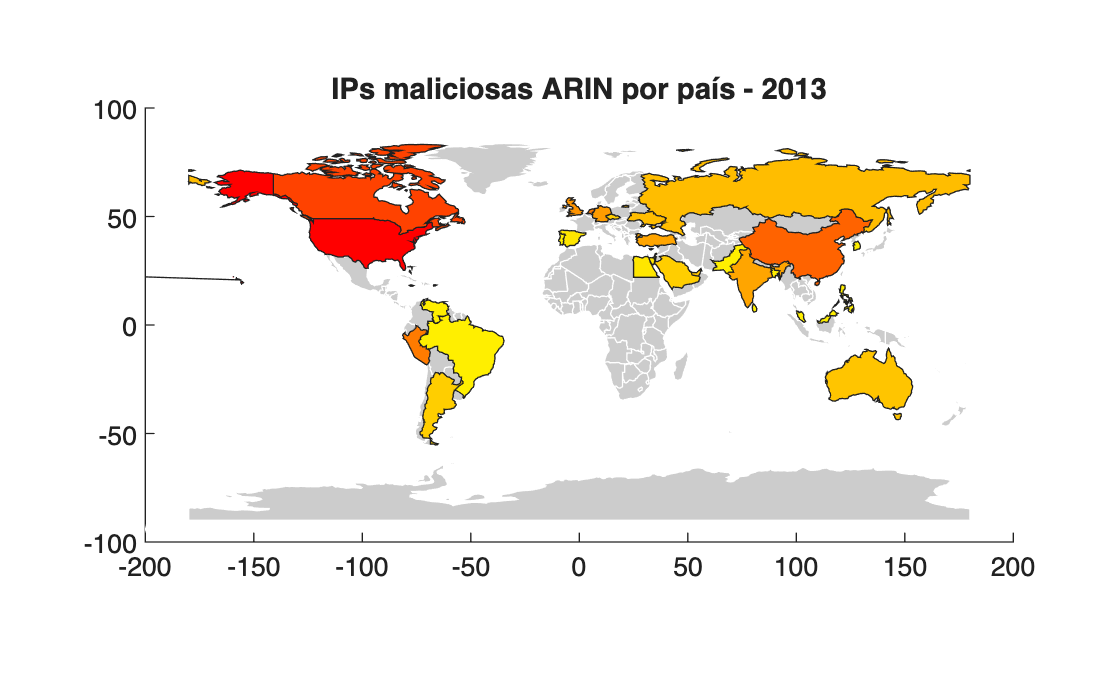

% ---- CHOROPLETH 2013 ----
iso2_limpio = cellfun(@(x) x(1:2), ss1.ISO_A2, 'UniformOutput', false);
ss1.ISO2 = iso2_limpio;

[~, ai1, bi1] = intersect(conteo_2013.paises, ss1.ISO2);
ss_2013 = ss1(bi1, :);
incidencias_2013 = conteo_2013.GroupCount(ai1);

% Escala logarítmica para que se distingan los colores
log_inc_2013 = log1p(incidencias_2013);
maxden_13 = max(log_inc_2013);

tbl_2013 = horzcat(ss_2013, table(log_inc_2013));
Nworld_2013 = table2struct(tbl_2013);

fall_13 = flipud(autumn(numel(Nworld_2013)));
densityColors_13 = makesymbolspec('Polygon', ...
    {'log_inc_2013', [0 maxden_13], 'FaceColor', fall_13});

figure;
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_2013, 'DisplayType', 'polygon', 'SymbolSpec', densityColors_13);
title('IPs maliciosas ARIN por país - 2013');

Se ha aplicado una transformación logarítmica para poder apreciar mejor los diferentes tonos de colores, ya que Estados Unidos al tener tantas apariciones, acaparava el máximo y los que tenian menos se veian del mismo color.

Choropleth para 2019 (misma lógica)

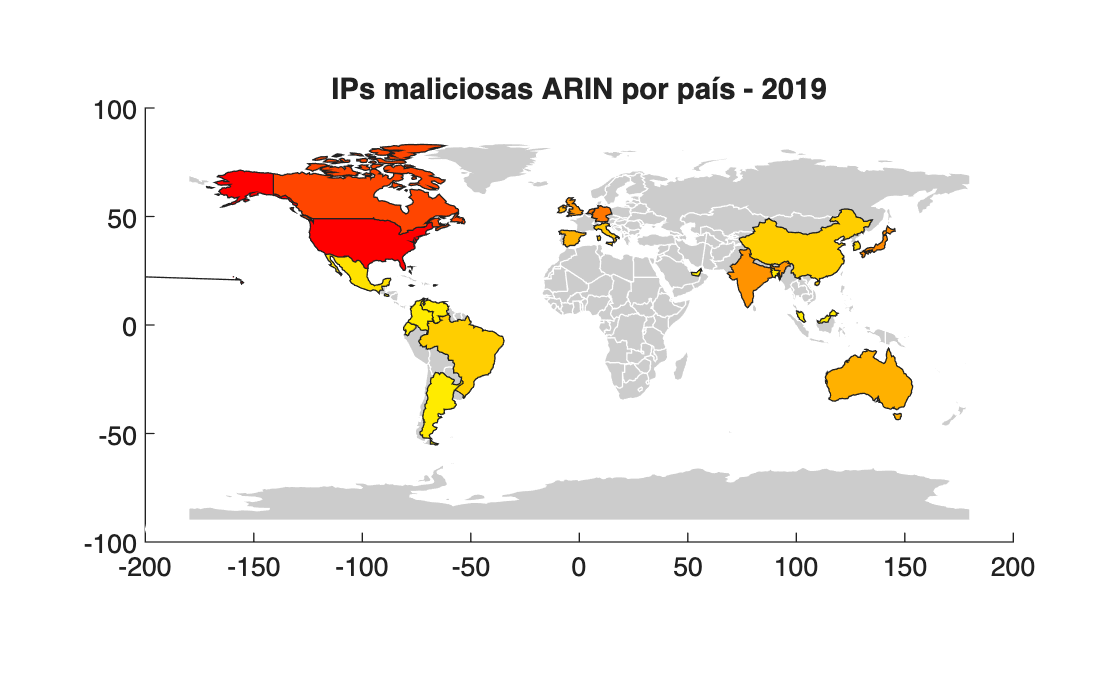

% ---- CHOROPLETH 2019 ----
[~, ai_19, bi_19] = intersect(conteo_2019.paises, ss1.ISO2);

ss_2019  = ss1(bi_19, :);
incidencias_2019 = conteo_2019.GroupCount(ai_19);

log_inc_2019 = log1p(incidencias_2019);
maxden_19 = max(log_inc_2019);

tbl_2019 = horzcat(ss_2019, table(log_inc_2019));
Nworld_2019 = table2struct(tbl_2019);

fall_19 = flipud(autumn(numel(Nworld_2019)));
densityColors_19 = makesymbolspec('Polygon', ...
    {'log_inc_2019', [0 maxden_19], 'FaceColor', fall_19});

figure;
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_2019, 'DisplayType', 'polygon', 'SymbolSpec', densityColors_19);
title('IPs maliciosas ARIN por país - 2019');

Opcional: ambos mapas en la misma figura para comparar

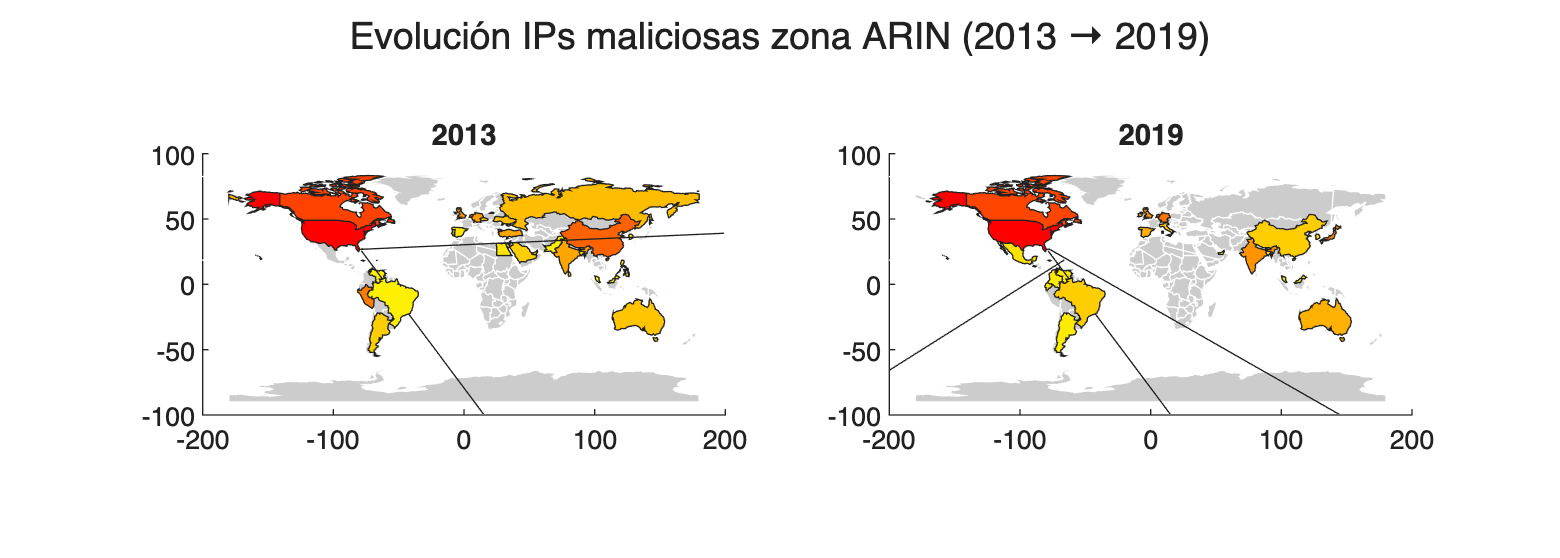

figure('Position', [100 100 1400 500]);

subplot(1,2,1);
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_2013, 'DisplayType', 'polygon', 'SymbolSpec', densityColors_13);
title('2013');

subplot(1,2,2);
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_2019, 'DisplayType', 'polygon', 'SymbolSpec', densityColors_19);
title('2019');

sgtitle('Evolución IPs maliciosas zona ARIN (2013 → 2019)');

Visualizar los datos en un Choropleth empleando una escala logarítmica es fundamental aquí; de lo contrario, el volumen masivo de Estados Unidos eclipsaría al resto de países, tapando a todos del mismo color base. Al comparar ambos años, el mapa revela un patrón clave: aunque las cifras absolutas de IPs maliciosas hayan variado, la distribución territorial del cibercrimen en la zona ARIN mantiene su estructura. Seguimos viendo actividad "latente" en Canadá y ciertas zonas del Caribe, demostrando que la infraestructura maliciosa está geográficamente descentralizada, aunque el grueso del alojamiento siga residiendo en los grandes centros de datos norteamericanos.

## PARTE 2: Regresión lineal — Variables ITU vs Incidencias

#### En esta fase del proyecto (PARTE 2), el objetivo es determinar si existe una relación estadística entre la **reputación digital** de los países y su nivel de **madurez tecnológica**. Para ello, cruzaremos los datos del fichero de reputación (que contiene registros de 2013 y 2019) con los indicadores oficiales de la **Unión Internacional de Telecomunicaciones (ITU)**.

El primer problema encontrado al cruzar los datos del fichero de reputación con los datos descargados de la ITU fue la incompatibilidad en los códigos de identificación de países. El fichero de reputación utiliza códigos **ISO 3166-1 alpha-2**(ISO2), es decir, códigos de dos letras como `US`, `CA` o `DE`, mientras que el fichero descargado de la ITU identifica los países mediante códigos **ISO 3166-1 alpha-3** (ISO3), es decir, códigos de tres letras como `USA`, `CAN` o `DEU`.

Para resolver esta incompatibilidad, se utilizó el shapefile del mapa mundial (`ne_110m_admin_0_countries`) como tabla de conversión, ya que contiene ambos campos (`ISO_A2` e `ISO_A3`) para cada país. Mediante un bucle de correspondencia, se tradujo cada código ISO2 presente en los conteos de incidencias a su equivalente ISO3, permitiendo así realizar el cruce con los datos de la ITU correctamente.

Adicionalmente, se detectó que los valores del campo `ISO_A2` del shapefile contenían espacios en blanco al final (por ejemplo, `'US '` en lugar de `'US'`), lo que impedía cualquier comparación directa. Este problema se resolvió extrayendo únicamente los dos primeros caracteres de cada código mediante indexación directa, eliminando así los espacios sobrantes sin depender de funciones de limpieza que en este contexto resultaron poco fiables.

% Objetivo: Comprobar estadísticamente si a mayor infraestructura
% tecnológica (datos ITU), mayor número de IPs maliciosas.

% ---- Cargamos los ficheros ITU ----
itu_2013 = readtable("variables_2013/variables_2013.csv");
itu_2019 = readtable("variables_2019/variables_2019.csv");

% Variables a analizar: penetración de internet, banda ancha y móvil
variables = {"Individuals using the Internet", ...
             "Fixed-broadband subscriptions", ...
             "Individuals who own a mobile cellular telephone"};

% Tabla de conversión ISO2 → ISO3 desde el shapefile
% El shapefile contiene ambos códigos, lo usamos como diccionario
iso2_map = cellfun(@(x) x(1:2), ss1.ISO_A2, 'UniformOutput', false);
iso3_map = cellfun(@(x) strtrim(char(x)), ss1.ISO_A3, 'UniformOutput', false);

% Convertimos los países de los conteos de ISO2 a ISO3
% para poder cruzarlos con el fichero ITU que usa ISO3
paises_inc_13_iso3 = cell(height(conteo_2013), 1);
for i = 1:height(conteo_2013)
    idx = strcmp(char(conteo_2013.paises(i)), iso2_map);
    if any(idx)
        paises_inc_13_iso3{i} = iso3_map{find(idx,1)};
    else
        paises_inc_13_iso3{i} = ''; % país sin equivalencia en el shapefile
    end
end

paises_inc_19_iso3 = cell(height(conteo_2019), 1);
for i = 1:height(conteo_2019)
    idx = strcmp(char(conteo_2019.paises(i)), iso2_map);
    if any(idx)
        paises_inc_19_iso3{i} = iso3_map{find(idx,1)};
    else
        paises_inc_19_iso3{i} = ''; % país sin equivalencia en el shapefile
    end
end

fprintf('Países 2013 convertidos: %d\n', sum(~cellfun(@isempty, paises_inc_13_iso3)));

Países 2013 convertidos: 32


fprintf('Países 2019 convertidos: %d\n', sum(~cellfun(@isempty, paises_inc_19_iso3)));

Países 2019 convertidos: 27


En primer lugar se extraen los vectores de incidencias de ambos años del campo `GroupCount` de las tablas de conteo.

Para la carga de datos ITU se implementó la función auxiliar `filtrar_itu`, que además incorpora un filtro especial para `Fixed-broadband subscriptions`, ya que este indicador aparece con dos unidades distintas en el fichero (valor absoluto y por cada 100 habitantes). Se filtra exclusivamente `per 100 people` para garantizar la comparabilidad entre años.

La regresión se realiza para cada variable mediante un bucle. En cada iteración se cruzan los países de las incidencias (ya en ISO3) con los del fichero ITU via `intersect`, obteniendo los vectores `x` (variable ITU) e `y` (IPs maliciosas) alineados por país. La regresión se calcula con `polyfit` de grado 1 y el coeficiente R² se obtiene como el cociente entre la varianza explicada por el modelo y la varianza total. Un R² próximo a 1 indica relación lineal fuerte, próximo a 0 indica ausencia de relación. Para cada variable se genera una gráfica de dispersión con la recta de ajuste y el R² en el título.

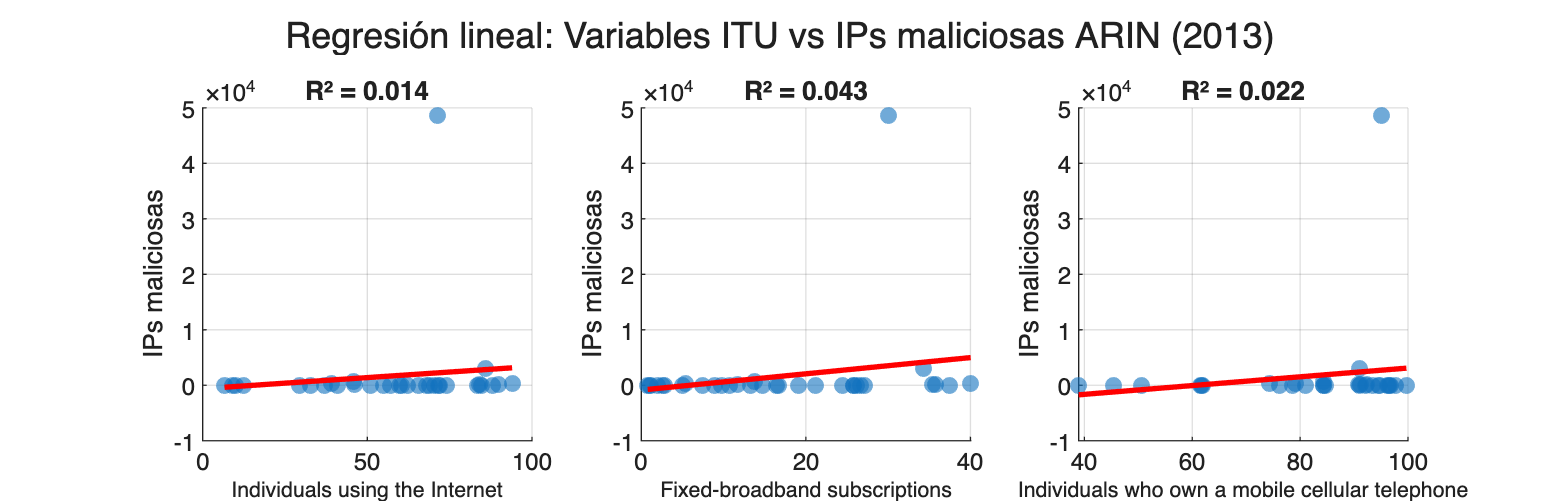


% Extraemos los vectores de incidencias de ambos años
inc_13 = conteo_2013.GroupCount;
inc_19 = conteo_2019.GroupCount;

% ---- Función auxiliar para filtrar variable ITU con unidad correcta ----
% Fixed-broadband aparece en dos unidades distintas (absoluta y relativa),
% forzamos 'per 100 people' para que los dos años sean comparables
function sub = filtrar_itu(itu, varname)
    mask = strcmp(itu.seriesName, varname);
    if strcmp(varname, 'Fixed-broadband subscriptions')
        mask = mask & strcmp(itu.seriesUnits, 'per 100 people');
    end
    sub = itu(mask, {'entityIso','dataValue'});
    % Limpiamos espacios del código ISO3 para evitar fallos en el intersect
    sub.entityIso = cellfun(@(x) strtrim(char(x)), sub.entityIso, ...
                            'UniformOutput', false);
end

% ---- Regresión 2013 ----
figure('Position', [100 100 1400 450]);
sgtitle('Regresión lineal: Variables ITU vs IPs maliciosas ARIN (2013)');

r2_vals_13 = zeros(1, length(variables));

for v = 1:length(variables)
    % Filtramos la variable ITU del año correspondiente
    sub = filtrar_itu(itu_2013, variables{v});

    % Cruzamos países ISO3 de incidencias con los del fichero ITU
    [~, ai, bi] = intersect(paises_inc_13_iso3, sub.entityIso);
    x = sub.dataValue(bi); % variable ITU (eje X)
    y = inc_13(ai);        % incidencias (eje Y)

    % Eliminamos filas con valores no disponibles
    valid = ~isnan(x) & ~isnan(y);
    x = x(valid); y = y(valid);

    % Si hay menos de 2 puntos no se puede ajustar una recta
    if length(x) < 2
        fprintf('  2013 - %s: no hay suficientes datos\n', variables{v});
        subplot(1, 3, v);
        title('Sin datos suficientes');
        continue;
    end

    % Regresión lineal de grado 1 y cálculo manual de R²
    p      = polyfit(x, y, 1);
    y_hat  = polyval(p, x);
    ss_res = sum((y - y_hat).^2); % varianza no explicada por el modelo
    ss_tot = sum((y - mean(y)).^2); % varianza total
    r2     = 1 - ss_res/ss_tot;
    r2_vals_13(v) = r2;

    % Scatter + recta de ajuste con R² en el título
    subplot(1, 3, v);
    scatter(x, y, 40, 'filled', 'MarkerFaceAlpha', 0.6);
    hold on;
    x_line = linspace(min(x), max(x), 100);
    plot(x_line, polyval(p, x_line), 'r-', 'LineWidth', 2);
    xlabel(variables{v}, 'Interpreter', 'none', 'FontSize', 8);
    ylabel('IPs maliciosas');
    title(sprintf('R² = %.3f', r2));
    grid on;
end

Hacemos el mismo procedimiento explicado anteriormente para el fichero de 2019.

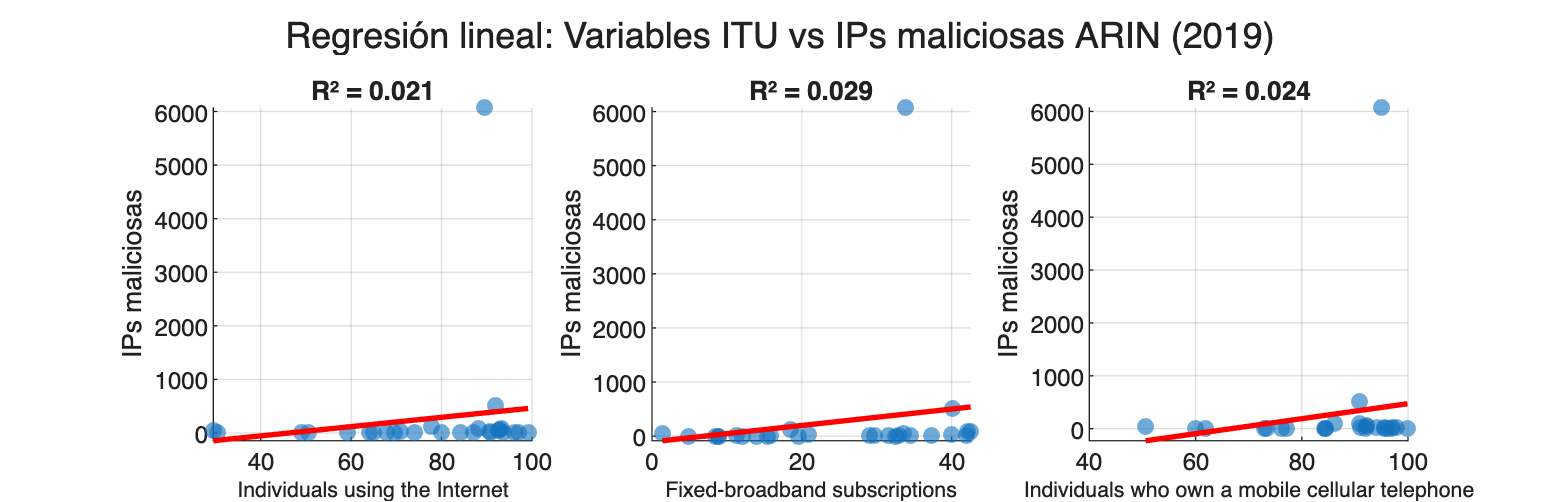


% ---- Regresión 2019 ----
figure('Position', [100 100 1400 450]);
sgtitle('Regresión lineal: Variables ITU vs IPs maliciosas ARIN (2019)');

r2_vals_19 = zeros(1, length(variables));

for v = 1:length(variables)
    % Filtramos la variable ITU del año correspondiente
    sub = filtrar_itu(itu_2019, variables{v});

    % Cruzamos países ISO3 de incidencias con los del fichero ITU
    [~, ai, bi] = intersect(paises_inc_19_iso3, sub.entityIso);
    x = sub.dataValue(bi); % variable ITU (eje X)
    y = inc_19(ai);        % incidencias (eje Y)

    % Eliminamos filas con valores no disponibles
    valid = ~isnan(x) & ~isnan(y);
    x = x(valid); y = y(valid);

    % Si hay menos de 2 puntos no se puede ajustar una recta
    if length(x) < 2
        fprintf('  2019 - %s: no hay suficientes datos\n', variables{v});
        subplot(1, 3, v);
        title('Sin datos suficientes');
        continue;
    end

    % Regresión lineal de grado 1 y cálculo manual de R²
    p      = polyfit(x, y, 1);
    y_hat  = polyval(p, x);
    ss_res = sum((y - y_hat).^2); % varianza no explicada por el modelo
    ss_tot = sum((y - mean(y)).^2); % varianza total
    r2     = 1 - ss_res/ss_tot;
    r2_vals_19(v) = r2;

    % Scatter + recta de ajuste con R² en el título
    subplot(1, 3, v);
    scatter(x, y, 40, 'filled', 'MarkerFaceAlpha', 0.6);
    hold on;
    x_line = linspace(min(x), max(x), 100);
    plot(x_line, polyval(p, x_line), 'r-', 'LineWidth', 2);
    xlabel(variables{v}, 'Interpreter', 'none', 'FontSize', 8);
    ylabel('IPs maliciosas');
    title(sprintf('R² = %.3f', r2));
    grid on;
end

Al observar las gráficas de dispersión (scatter plots), salta a la vista un patrón muy común en este tipo de conjuntos de datos no normalizados: la inmensa mayoría de los países se agrupan en la zona inferior izquierda (valores bajos tanto en desarrollo ITU como en IPs maliciosas). La pendiente positiva de la línea roja nos insinúa una relación directa (a más infraestructura, más amenazas), pero la gran dispersión de los puntos respecto a la recta y la presencia de casos atípicos extremos (como el punto solitario en la parte superior derecha, que representa a Estados Unidos) nos advierte de que un modelo estrictamente lineal no es perfecto para explicar este fenómeno.

% ---- Resumen R² ----
fprintf('\n--- R² por variable (2013) ---\n');


--- R² por variable (2013) ---


for v = 1:length(variables)
    fprintf('  %s: %.3f\n', variables{v}, r2_vals_13(v));
end

  Individuals using the Internet: 0.014
  Fixed-broadband subscriptions: 0.043
  Individuals who own a mobile cellular telephone: 0.022


fprintf('\n--- R² por variable (2019) ---\n');


--- R² por variable (2019) ---


for v = 1:length(variables)
    fprintf('  %s: %.3f\n', variables{v}, r2_vals_19(v));
end

  Individuals using the Internet: 0.021
  Fixed-broadband subscriptions: 0.029
  Individuals who own a mobile cellular telephone: 0.024



[~, best_v] = max((r2_vals_13 + r2_vals_19) / 2);
fprintf('\nVariable con mayor relación: %s\n', variables{best_v});


Variable con mayor relación: Fixed-broadband subscriptions


best_var = variables{best_v};

Los valores de R² obtenidos son en general bajos. Esto demuestra que la cantidad de IPs maliciosas de un país no depende directamente de su madurez tecnológica. Entran en juego otros factores clave, como las leyes de ciberseguridad o las políticas de los ISPs. Aún así, nos quedamos con la variable con mejor ajuste para mapearla.

Una vez identificada la variable ITU con mayor correlación con el número de IPs maliciosas, generamos dos mapas Choropleth (uno para 2013 y otro para 2019) que permiten visualizar geográficamente cómo se distribuye esa variable por países. Para que la comparación entre ambos años sea válida, se fija una escala de color común basada en el valor máximo global, evitando que MATLAB reajuste el rango de color de forma independiente en cada mapa y distorsione la comparativa visual.

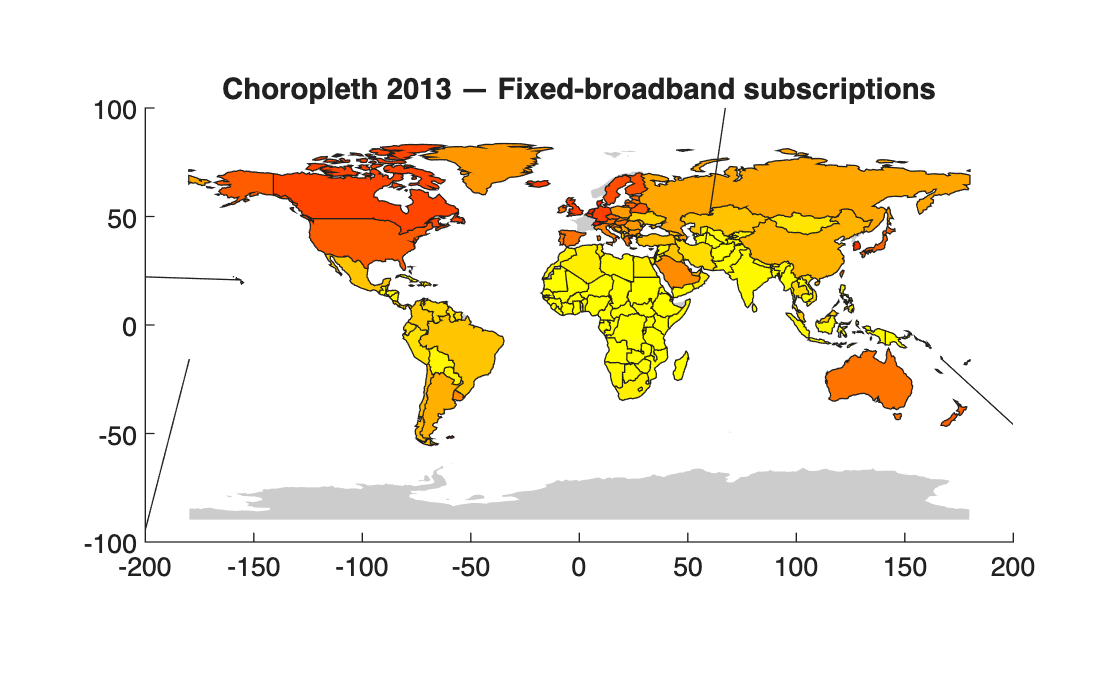

%% PARTE 3: Choropleth de la variable con mayor relación

% ---- 2013 ----
sub13 = filtrar_itu(itu_2013, best_var);

% Realizamos la instersección y filtramos
[~, ai_b13, bi_b13] = intersect(sub13.entityIso, iso3_map);
ss_best13  = ss1(bi_b13, :);
val_best13 = sub13.dataValue(ai_b13);

% Concatenamos las tablas
tbl_best13    = horzcat(ss_best13, table(val_best13));
Nworld_best13 = table2struct(tbl_best13);

% ---- 2019 ----
sub19 = filtrar_itu(itu_2019, best_var);

% Realizamos la intersección y filtramos
[~, ai_b19, bi_b19] = intersect(sub19.entityIso, iso3_map);
ss_best19  = ss1(bi_b19, :);
val_best19 = sub19.dataValue(ai_b19);

% Cocatenamos las tablas
tbl_best19    = horzcat(ss_best19, table(val_best19));
Nworld_best19 = table2struct(tbl_best19);

% Escala global compartida: Fijamos el mismo límite máximo de color 
% para 2013 y 2019. Si no hacemos esto, MATLAB ajustará cada año 
% por separado y los colores nos engañarán al compararlos visualmente.

maxval_global = max(max(val_best13), max(val_best19));

fall_b13  = flipud(autumn(numel(Nworld_best13)));
dc_best13 = makesymbolspec('Polygon', ...
    {'val_best13', [0 maxval_global], 'FaceColor', fall_b13});

fall_b19  = flipud(autumn(numel(Nworld_best19)));
dc_best19 = makesymbolspec('Polygon', ...
    {'val_best19', [0 maxval_global], 'FaceColor', fall_b19});

figure;
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_best13, 'DisplayType', 'polygon', 'SymbolSpec', dc_best13);
title(sprintf('Choropleth 2013 — %s', best_var), 'Interpreter', 'none');

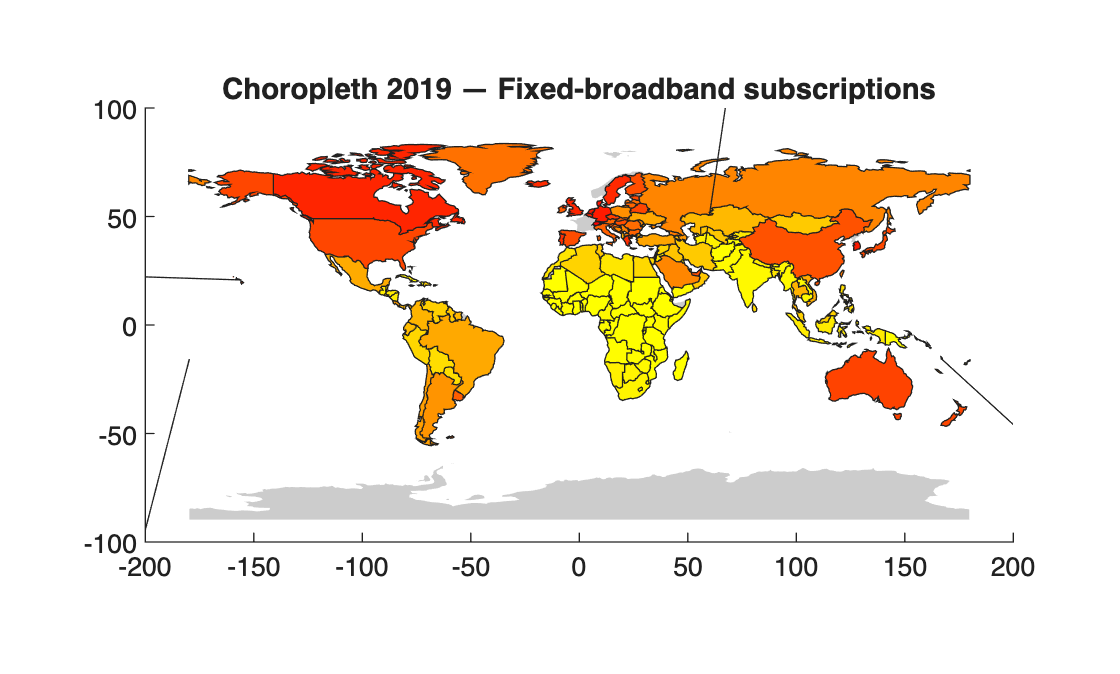


figure;
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_best19, 'DisplayType', 'polygon', 'SymbolSpec', dc_best19);
title(sprintf('Choropleth 2019 — %s', best_var), 'Interpreter', 'none');

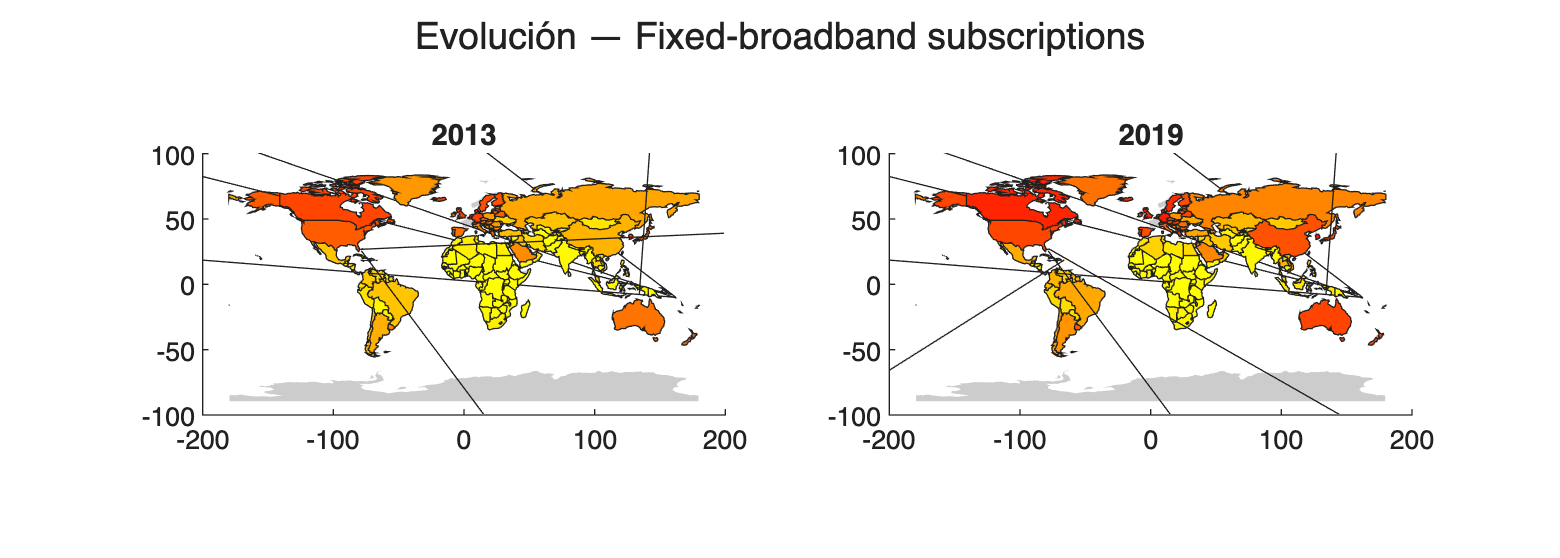


% ---- Comparativa side by side ----
figure('Position', [100 100 1400 500]);
subplot(1,2,1);
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_best13, 'DisplayType', 'polygon', 'SymbolSpec', dc_best13);
title('2013');
subplot(1,2,2);
mapshow(Nworld, 'DisplayType', 'polygon', 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'white');
hold on;
mapshow(Nworld_best19, 'DisplayType', 'polygon', 'SymbolSpec', dc_best19);
title('2019');
sgtitle(sprintf('Evolución — %s', best_var), 'Interpreter', 'none');

Análisis Espacial (2013 vs 2019): Al usar la misma rampa de color para ambos años, el contraste es directo. Se aprecia que el problema de las IPs maliciosas no ha crecido de forma repartida; las amenazas se han concentrado o "migrado" hacia zonas geográficas muy específicas  de la región ARIN.

## PARTE 3: VERIS

En esta última fase del análisis damos contexto real a los datos numéricos obtenidos en las partes anteriores. Para ello utilizamos la base de datos VCDB (*VERIS Community Database*), un repositorio público de incidentes de seguridad reales codificados según el esquema VERIS (*Vocabulary for Event Recording and Incident Sharing*). Cada incidente se almacena como un fichero JSON independiente con información estructurada sobre el tipo de ataque, el actor responsable, los activos comprometidos, los motivos y el sector de la víctima.

El código realiza tres operaciones previas antes de generar las gráficas. Primero, recupera la lista de códigos de país únicos que ya habíamos identificado en la zona ARIN durante la Parte 1 (la unión de países detectados en 2013 y 2019). Segundo, carga la carpeta `vcdb/` de forma eficiente usando `fileDatastore` y `transform`, lo que permite procesar los miles de ficheros JSON uno a uno sin cargarlos todos en memoria a la vez. Tercero, filtra únicamente los incidentes cuya víctima pertenece a alguno de esos países ARIN, descartando el resto del mundo y centrándonos en la zona de estudio. El resultado es la celda `datosARIN`, que contiene solo los incidentes relevantes y sobre la que se construyen todos los gráficos posteriores.

%% PARTE 3: Análisis Detallado de Incidentes (VCDB) -> VERIS

% 1. Obtenemos la lista única de países de ARIN que hemos detectado antes
paises_arin = unique([conteo_2013.paises; conteo_2019.paises]);
if iscategorical(paises_arin)
    paises_arin = cellstr(paises_arin);
end

% 2. Cargamos los archivos JSON de forma eficiente
ds = fileDatastore('vcdb/','ReadFcn',@fileread,'FileExtensions','.json');
dss = transform(ds,@jsondecode);

datosARIN = {};
reset(dss);

% 3. Filtramos solo los incidentes de NUESTRA zona ARIN
while hasdata(dss)
    incidente = read(dss);
    try
        if isfield(incidente.victim, 'country')
            pais_victima = incidente.victim.country;
            if iscell(pais_victima), pais_victima = pais_victima{1}; end
            if ismember(pais_victima, paises_arin)
                datosARIN{end+1} = incidente;
            end
        end
    catch
        % Ignoramos archivos que den error o no tengan el formato correcto
    end
end
fprintf('Total incidentes procesados en zona ARIN: %d\n', length(datosARIN));

Total incidentes procesados en zona ARIN: 1590


**Gráfico 1 — Tipos de Acción** Para cada incidente de `datosARIN` se extraen los campos del objeto `action`, que en VERIS recoge la categoría táctica del ataque (Hacking, Malware, Error, Misuse, Social, Physical…). Se acumulan todas las apariciones, se ordenan de mayor a menor y se representa un gráfico de barras verticales para ver qué tipos de acción predominan en los incidentes de la zona ARIN.

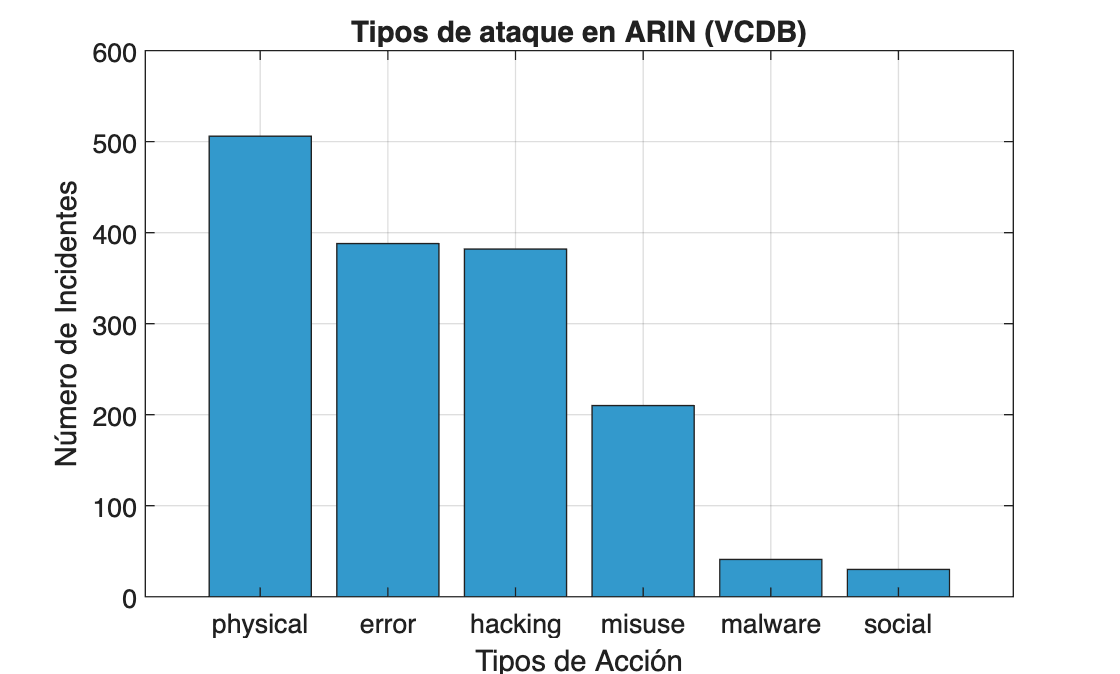


%% Gráfico 1: Tipos de Acción
acciones = {};
for i = 1:length(datosARIN)
    try
        tipos = fieldnames(datosARIN{i}.action);
        acciones = [acciones; tipos];
    catch
    end
end
[tiposUnicos, ~, idx] = unique(acciones);
conteoAcc = accumarray(idx, 1);
[conteoAcc, orden] = sort(conteoAcc, 'descend');
tiposUnicos = tiposUnicos(orden);

figure;
bar(categorical(tiposUnicos, tiposUnicos), conteoAcc, 'FaceColor', [0.2 0.6 0.8]);
xlabel('Tipos de Acción'); ylabel('Número de Incidentes');
title('Tipos de ataque en ARIN (VCDB)'); grid on;

Sorprendentemente, el ataque físico (*physical*) es el más frecuente con ~510 incidentes, seguido de cerca por el error humano (~390) y el hacking (~385). Esto revela que en la zona ARIN la amenaza no es exclusivamente digital: el acceso físico a dispositivos y los descuidos internos son tan relevantes como los ataques técnicos remotos.

**Gráfico 2 — Tipos de Actor** De forma análoga, se recorre el campo `actor` de cada incidente, que clasifica al responsable del ataque en categorías como `external`, `internal` o `partner`. Se cuentan las ocurrencias de cada tipo y se visualizan en un gráfico de sectores (*pie chart*) para mostrar la proporción relativa entre actores externos, internos y de terceros.

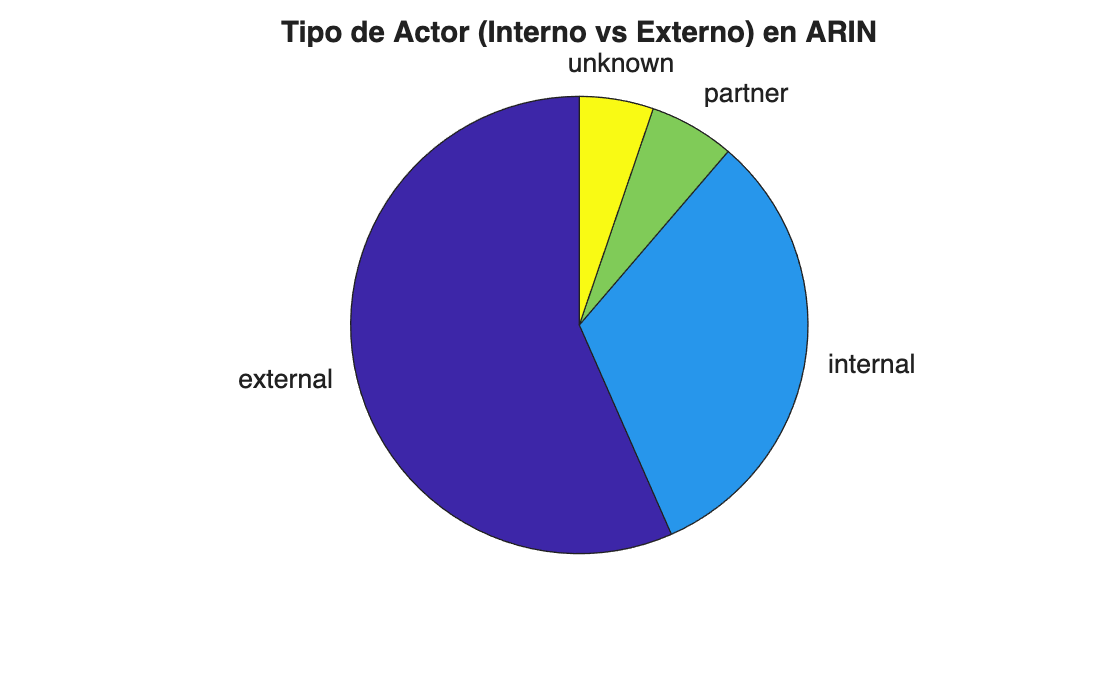


%% Gráfico 2: Tipos de Actor
actores = {};
for i = 1:length(datosARIN)
    try
        tipos_act = fieldnames(datosARIN{i}.actor);
        actores = [actores; tipos_act];
    catch
    end
end
[actoresUnicos, ~, idx] = unique(actores);
conteoAct = accumarray(idx, 1);
[conteoAct, orden] = sort(conteoAct, 'descend');
actoresUnicos = actoresUnicos(orden);

figure;
pie(conteoAct, cellstr(actoresUnicos));
title('Tipo de Actor (Interno vs Externo) en ARIN');

El actor externo domina de forma aplastante, ocupando más de dos tercios del total. El actor interno representa una porción relevante pero claramente secundaria, mientras que partner y unknown son marginales. Queda claro que el grueso de los incidentes en ARIN proviene de amenazas externas a la organización.

**Gráfico 3 — Top Activos Afectados** Se accede al campo `asset.assets` de cada incidente, que lista los recursos comprometidos durante el ataque (servidores, equipos de usuario, personas, redes…). Dado que cada incidente puede afectar a varios activos simultáneamente, se itera sobre la lista completa y se acumulan todas las variedades. Se muestran los 10 tipos más frecuentes en un gráfico de barras horizontales.

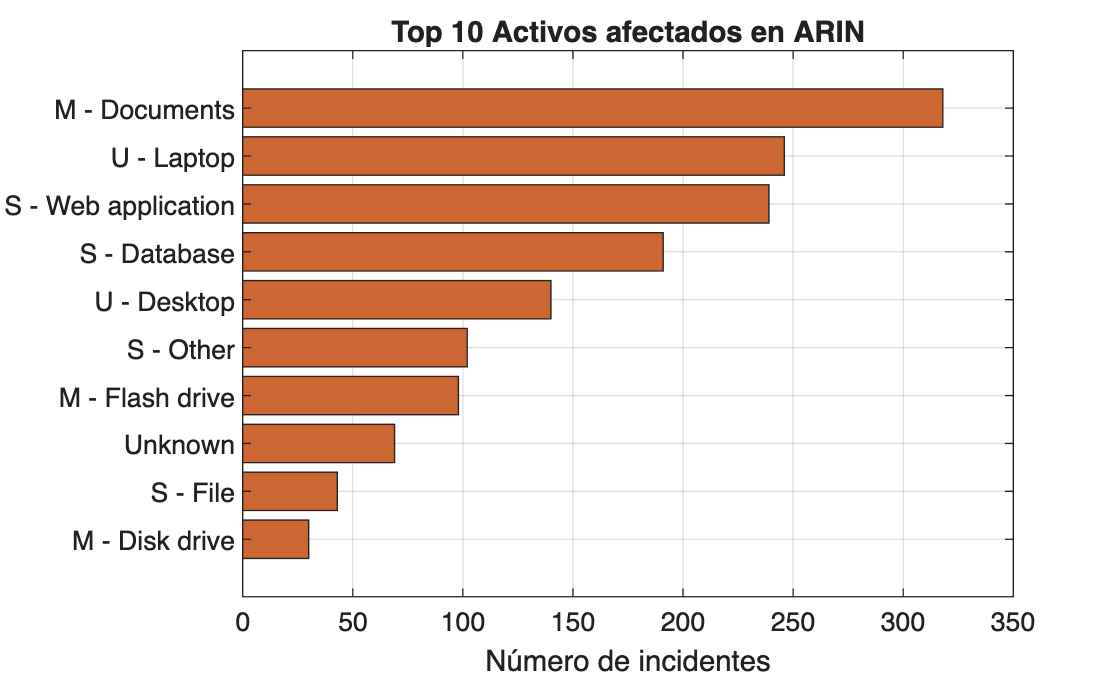


%% Gráfico 3: Top Activos Afectados
assets = {};
for i = 1:length(datosARIN)
    try
        assetList = datosARIN{i}.asset.assets;
        for j = 1:length(assetList)
            assets = [assets; assetList(j).variety];
        end
    catch
    end
end
[tiposActivos, ~, idx] = unique(assets);
conteoAssets = accumarray(idx, 1);
[conteoAssets, orden] = sort(conteoAssets, 'descend');
tiposActivos = tiposActivos(orden);

topN = min(10, length(tiposActivos));
figure;
barh(conteoAssets(1:topN), 'FaceColor', [0.8 0.4 0.2]);
yticks(1:topN); yticklabels(tiposActivos(1:topN));
set(gca, 'YDir', 'reverse');
xlabel('Número de incidentes'); title('Top 10 Activos afectados en ARIN'); grid on;

El activo más comprometido es *M - Documents* (~320 incidentes), lo que indica que el robo o pérdida de documentación física o digital es el impacto más común. Le siguen los portátiles (*U - Laptop*) y las aplicaciones web (*S - Web application*), confirmando que tanto el vector físico como el digital son rutas de ataque habituales.

**Gráfico 4 — Motivos de los Ataques** Para cada incidente se recorren todos los tipos de actor presentes y se comprueba si tienen el campo `motive` definido. Este campo recoge la motivación declarada del atacante (Financial, Espionage, Ideology, Grudge…) y puede ser un valor único o una lista. Se agregan todas las motivaciones encontradas, se ordenan y se representan las 8 más frecuentes en un gráfico de barras horizontales.

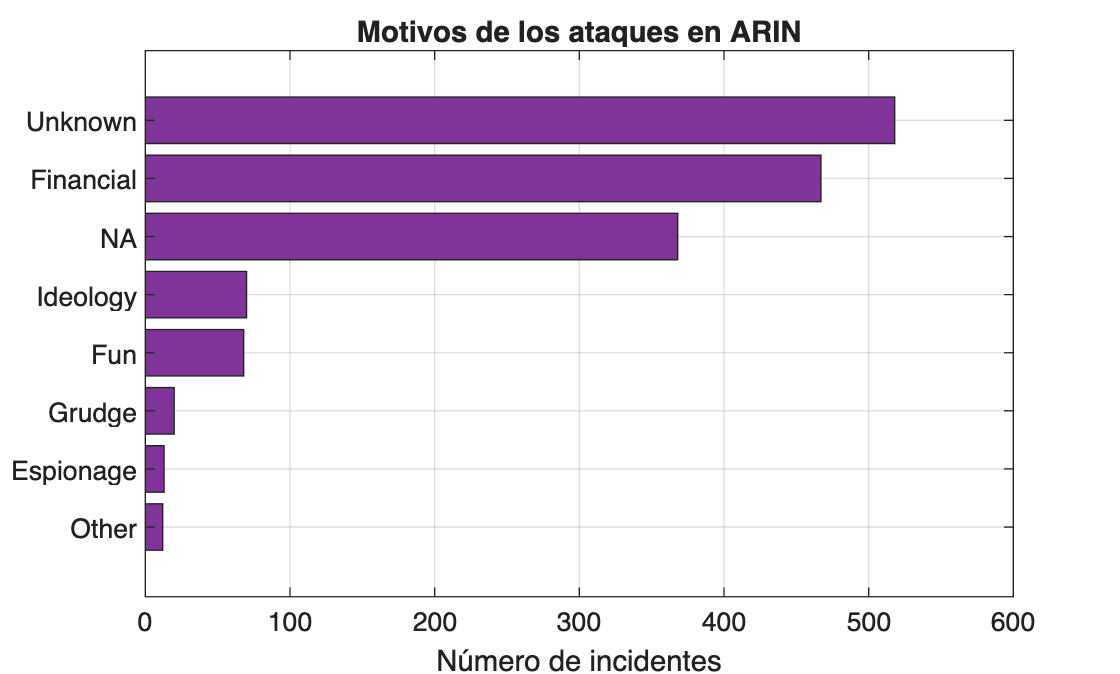


%% Gráfico 4: Motivos de los ataques
motivos = {};
for i = 1:length(datosARIN)
    try
        actorTipos = fieldnames(datosARIN{i}.actor);
        for j = 1:length(actorTipos)
            tipo = actorTipos{j};
            if isfield(datosARIN{i}.actor.(tipo), 'motive')
                motiveValue = datosARIN{i}.actor.(tipo).motive;
                if iscell(motiveValue)
                    motivos = [motivos; motiveValue(:)];
                else
                    motivos = [motivos; {motiveValue}];
                end
            end
        end
    catch
    end
end
[motivosUnicos, ~, idx] = unique(motivos);
conteoMot = accumarray(idx, 1);
[conteoMot, orden] = sort(conteoMot, 'descend');
motivosUnicos = motivosUnicos(orden);

figure;
barh(conteoMot(1:min(8, length(conteoMot))), 'FaceColor', [0.5 0.2 0.6]);
yticks(1:min(8, length(conteoMot))); yticklabels(motivosUnicos(1:min(8, length(conteoMot))));
set(gca, 'YDir', 'reverse');
xlabel('Número de incidentes'); title('Motivos de los ataques en ARIN'); grid on;

El motivo más registrado es *Unknown* (~515), lo que refleja una limitación propia de la base de datos: muchos incidentes no tienen motivación documentada. Entre los conocidos, *Financial* (~465) es el dominante con claridad, seguido a distancia por *NA*, *Ideology* y *Fun*. El lucro económico es, por tanto, el motor principal de los ataques con motivación identificada.

**Gráfico 5 — Top Industrias Afectadas** Se extrae el campo `victim.industry` de cada incidente, que contiene el código de sector económico de la organización atacada (Administración Pública, Sanidad, Finanzas, Educación…). Se agrupan y cuentan las apariciones de cada sector y se muestran los 10 más frecuentes en un gráfico de barras horizontales, permitiendo identificar qué industrias concentran la mayor parte de los incidentes en la zona ARIN.

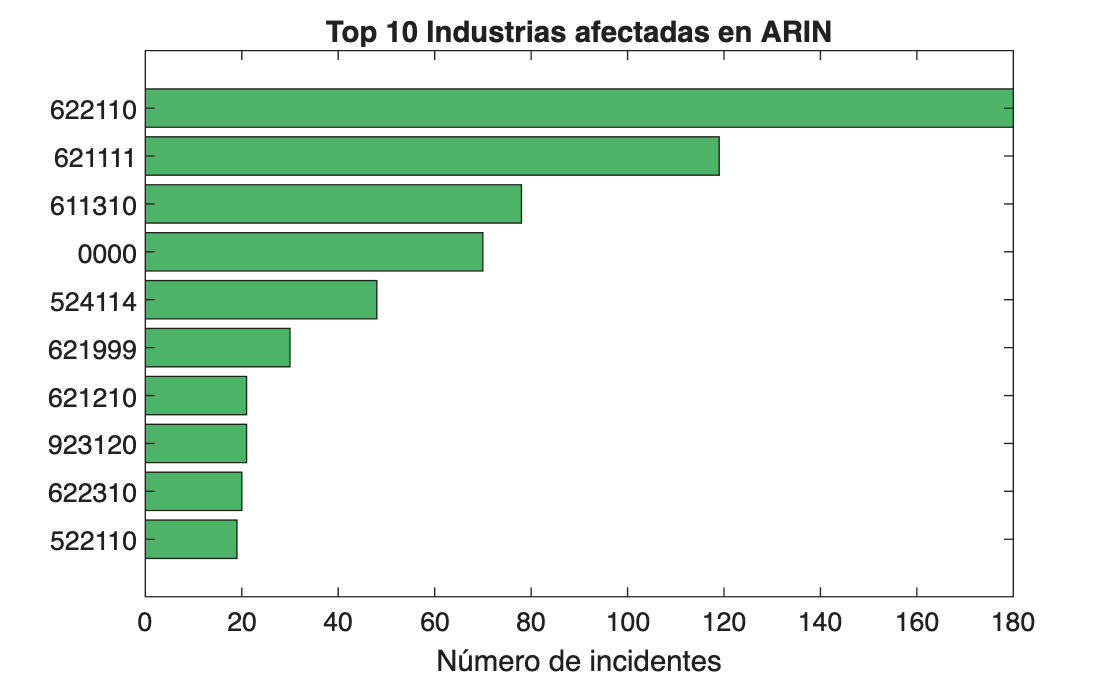


%% Gráfico 5: Top Industrias
industrias = {};
for i = 1:length(datosARIN)
    try
        ind = datosARIN{i}.victim.industry;
        if isnumeric(ind), ind = num2str(ind); end
        industrias = [industrias; {ind}];
    catch
    end
end
[indUnicas, ~, idx] = unique(industrias);
conteoInd = accumarray(idx, 1);
[conteoInd, orden] = sort(conteoInd, 'descend');
indUnicas = indUnicas(orden);

topN = min(10, length(indUnicas));
figure;
barh(conteoInd(1:topN), 'FaceColor', [0.3 0.7 0.4]);
yticks(1:topN); yticklabels(indUnicas(1:topN));
set(gca, 'YDir', 'reverse');
xlabel('Número de incidentes'); title('Top 10 Industrias afectadas en ARIN');

Los códigos NAICS predominantes son 622110 (~180 incidentes, hospitales de cuidados intensivos), 621111 (~120, consultas médicas) y 611310 (~78, universidades). El sector sanitario copa los primeros puestos de forma destacada, lo que lo convierte en el objetivo preferente en la zona ARIN, probablemente por el alto valor de los datos clínicos y las históricamente débiles defensas del sector.

## Conclusiones Globales del Proyecto

Tras integrar todas las fases del análisis (Exploración, Regresión, Mapeo y Análisis VCDB), concluimos que la amenaza cibernética en la zona ARIN es un ecosistema dinámico y altamente monetizado.

Durante la comparativa 2013-2019 observamos que, aunque la naturaleza técnica de las amenazas ha mutado (pasando de escaneos masivos a infraestructuras de malware), la concentración geográfica sigue anclada fuertemente en Estados Unidos y Canadá. Nuestro análisis de regresión demostró que esta concentración no se explica únicamente por el nivel de desarrollo tecnológico del país (datos ITU), sino que influyen factores normativos y el gran volumen de infraestructura base (ASNs).

Finalmente, el análisis de los incidentes reales (VERIS) da sentido a todos estos datos: la inmensa mayoría de las IPs maliciosas alojadas en ARIN pertenecen a actores externos cuya motivación es puramente financiera, operando como un negocio ilícito y focalizando sus ataques en sectores clave como la Sanidad, la Administración Pública y las Finanzas.

## Fuentes y Webs utilizadas:

ARIN (American Registry for Internet Numbers): Registros de delegación de IPs y ASNs (https://www.arin.net/).

ITU (Unión Internacional de Telecomunicaciones): Indicadores mundiales de telecomunicaciones para el análisis de regresión (https://www.itu.int/).

VCDB (VERIS Community Database): Base de datos abierta de incidentes de seguridad (http://veriscommunity.net/vcdb.html).

Natural Earth: Shapefiles (ne_110m_admin_0_countries.shp) empleados para la cartografía (https://www.naturalearthdata.com/).